# Example: Estimate 2-D Target States Using `trackingKF`

## Initialize Estimation Model 

Specify an initial position and velocity for a target that you assume moving in 2-D. The simulation lasts 20 seconds with a sample time of 0.2 seconds.

rng(1);    % For repeatable results
dt = 0.005;     % seconds
simTime = .9; % seconds
tspan   = 0:dt:simTime;

m=0.3;%Kg for the box
m_ee=2;%Kg for the end effector's mass, equivalent to inertia
mu=0.3;%Coefficient of friction
g=-9.81;%N/Kg gravity
restit = 0.7;%Restitution factor

flux = 1;%m/s, Define the flux for the hit
V_EE = flux * (1 + (m/m_ee))/(1+restit);%Get the end-effector speed required to achieve target flux

X_0 = 0;%Initial position of box
D_0 = 0.1;%Initial distance

Impulse_type = 0;%0 for impulse, 1 for gaussian

trueInitialState = [X_0; 0; 0; D_0; V_EE; 0]; % [x;vx;f;d;v_ee;fh]
processNoise = diag([0; 0; 0; 0; 0 ; 0]); % No process noise in this model, but from report : Process noise matrix diag([0.01; 0.1; 0.14; 0.01])

Create a measurement noise covariance matrix, assuming that the target measurements consist of its position states.

measureNoise = 0.005^2; % Measurement noise matrix

The matrix specifies a standard deviation of 2 meters in both the x- and y-directions. 

Preallocate variables in which to save estimation results.

numSteps = length(tspan);
trueStates = NaN(6,numSteps);
trueStates(:,1) = trueInitialState;
estimateStates = NaN(3,numSteps);
Xf_pred = NaN(1,numSteps);

## Obtain True States and Measurements

Propagate the constant velocity model, and generate the measurements with noise. 

%sigma_1=3; %Max amplitude of the Hitting force
sigma_2=0.05; %Standard deviation
sigma_1= m*((1+restit)^2 * flux^2) / (2 * sigma_2 * sqrt(2+pi)); 

%Note that the total force transmitted through impact is equal to :
%Integral Fh over d = sigma_1 * sigma_2 * sqrt(2*pi)

% [x;vx;f;d;v_ee;fh]
A = [1  dt  ((dt^2)/(2*m))  0 0 ((dt^2)/(2*m));
     0  1   dt/m            0 0 dt/m; 
     0  0   1               0 0 0;
     0  dt  0               1 -dt 0;
     0  0   0           0 1 -dt/m_ee;
     0  0   0               0 0 0];
C = [1 0 0 0 0 0];
for i = 2:length(tspan)
    trueStates(:,i) = A*trueStates(:,i-1) + sqrt(processNoise)*randn(6,1);
    if Impulse_type == 1
        trueStates(6,i) = sigma_1 * exp(-(trueStates(4,i)^2)/(2*sigma_2^2)); %Modulate applied force by distance
    else
       if trueStates(4,i)<0
           trueStates(2,i) = (1+restit) * flux;%V+ = (1+restit) * flux
           trueStates(5,i) = (trueStates(2,i)*m) / (m_ee^2 / trueStates(5,i));%Xe+ = m*v+ / m_ee^2*v_ee- 
       end
    end
    if abs(trueStates(2,i)) > 6e-3 %If speed is high enough, apply friction ; prevent osicllations around 0 speed
        trueStates(3,i) = mu*g*m*(trueStates(2,i)/abs(trueStates(2,i)));%f=m*g*mu*v/abs(v)
    else trueStates(3,i) = 0;
    end
end
measurements = C*trueStates + sqrt(measureNoise)*randn(1,numSteps);


Plot the true trajectory and the measurements.

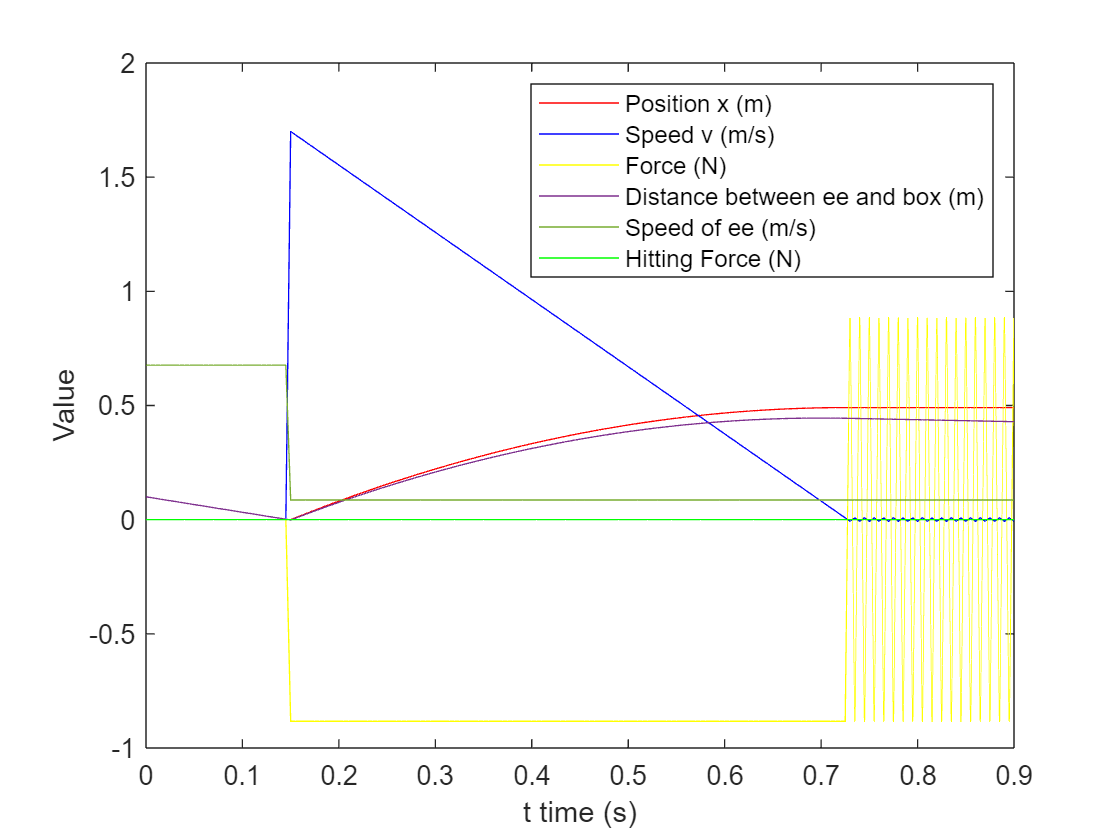

figure
plot(tspan,trueStates(1,:),"r",DisplayName="Position x (m)")
hold on
plot(tspan,trueStates(2,:),"b",DisplayName="Speed v (m/s)")
plot(tspan,trueStates(3,:),"y",DisplayName="Force (N)")
plot(tspan,trueStates(4,:),DisplayName="Distance between ee and box (m)")
plot(tspan,trueStates(5,:),DisplayName="Speed of ee (m/s)")
plot(tspan,trueStates(6,:),"g",DisplayName="Hitting Force (N)")
legend
xlabel("t time (s)")
ylabel("Value")

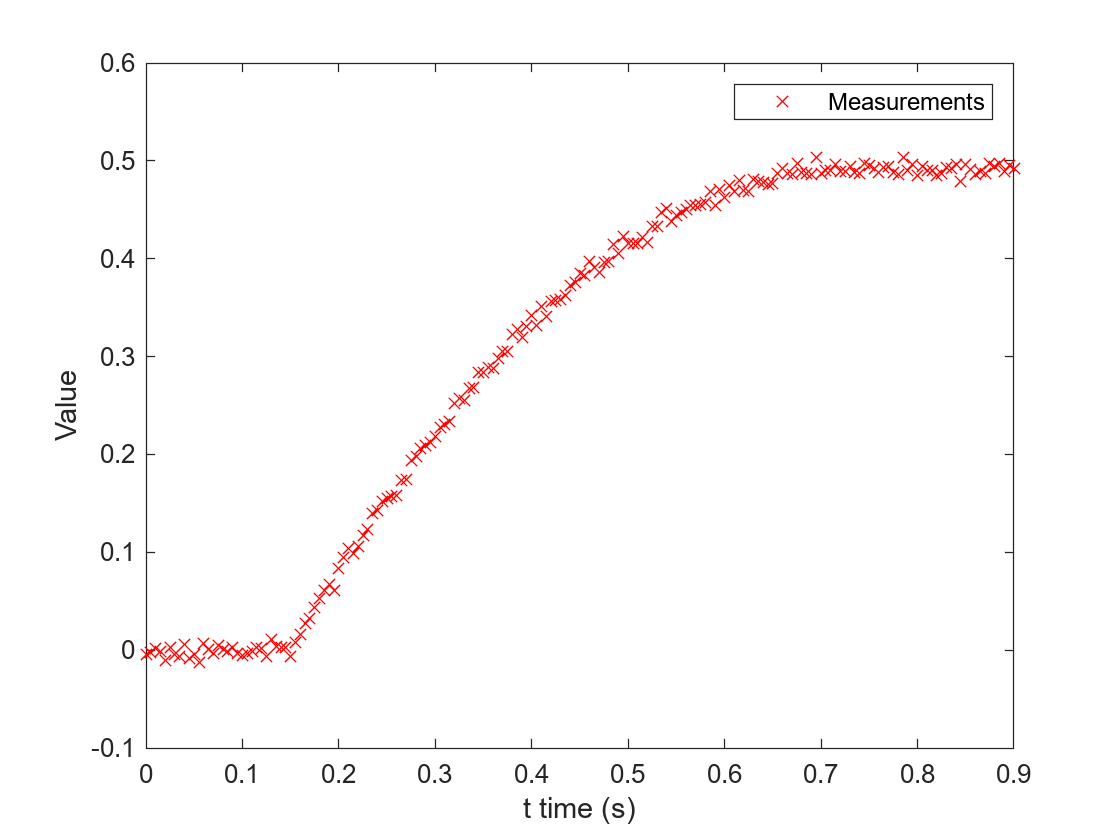

figure
plot(tspan,measurements(1,:),"rx",DisplayName="Measurements")
legend
xlabel("t time (s)")
ylabel("Value")

## Initialize Linear Kalman Filter

Initialize the filter with a state of `[40; 0; 160; 0]`, which is far from the true initial state.  Normally, you can use the initial measurement to construct an initial state as `[measurements(1,1);0 ; measurements(2,1); 0]`. Here, you use an erroneous initial state, which enables you to test if the filter can quickly converge on the truth.

H=[1 0 0];
filter = trackingKF(MotionModel="1D Constant Acceleration",State=[0; 0; 0], ...
    MeasurementModel=H,MeasurementNoise=sqrt(measureNoise))

filter =   trackingKF with properties:

               State: [3×1 double]
     StateCovariance: [3×3 double]

         MotionModel: '1D Constant Acceleration'
        ProcessNoise: 1

    MeasurementModel: [1 0 0]
    MeasurementNoise: 0.0050

     MaxNumOOSMSteps: 0

     EnableSmoothing: 0


estimateStates(:,1) = filter.State;

## Run Linear Kalman Filter and Show Results

Run the filter by recursively calling the `predict` and `correct` object functions. From the results, the estimates converge on the truth quickly. In fact, the linear Kalman filter has an exponential convergence speed.

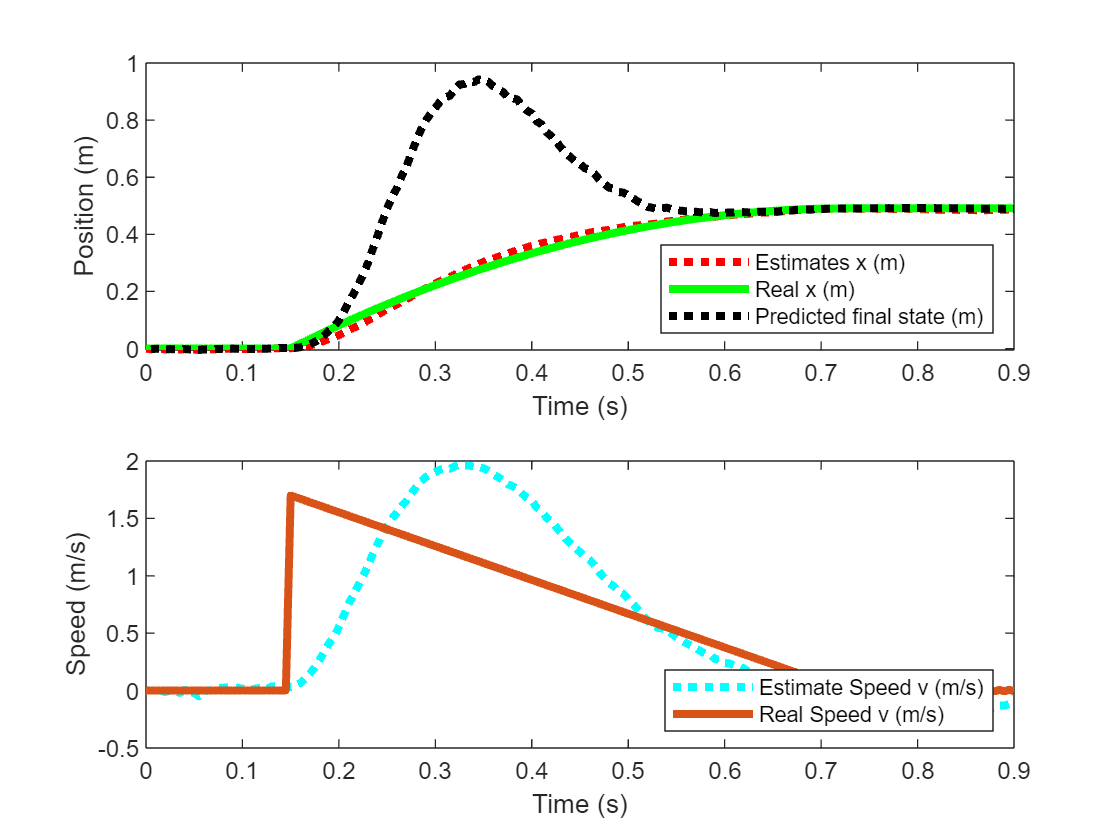

for i=2:length(tspan)
    predict(filter,dt)
    estimateStates(:,i) = correct(filter,measurements(:,i));
    Xf_pred(i) = estimateStates(1,i) + (0.5 * estimateStates(2,i)^2 / (mu * 9.81));
end

figure
subplot(2,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final state (m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(2,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
hold on
plot(tspan,trueStates(2,:),'LineWidth',3,DisplayName="Real Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")


%subplot(3,1,3)
%plot(tspan,trueStates(3,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
%hold on
%plot(tspan,estimateStates(3,:),":",'LineWidth',3,DisplayName="Estimate Force (N)")
%legend(Location="southeast")

*Copyright 2021 The MathWorks, Inc.*